An implementation of the variational stochastic gradient descent algorithm for noisy gradient evaluations.

Added reflective boundaries to allow constrained optimization 

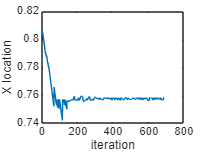

x0 = rand();

[x,Fx,xv,fv] = VSGD(@(x) forr(x),x0,'lr',0.001,'lb',0,'ub',1,'gamma',2,'iters',2000,'tol',1*10^(-5));

figure
plot(xv)
xlabel('iteration')
ylabel('X location')

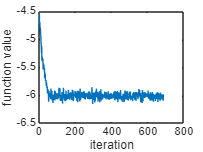


figure
plot(fv)
xlabel('iteration')
ylabel('function value')

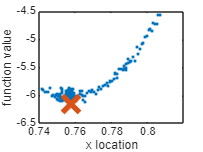


figure
plot(xv,fv,'.')
hold on
plot(x,Fx,'x','MarkerSize',18,'LineWidth',4)

xlabel('x location')
ylabel('function value')

function [y,dy] = forr(x)

y = ((6*x-2).^2).*sin(12*x-4)  + normrnd(0*x,0.05);
dy =12*(6*x-2).*(sin(12*x-4) + (6*x-2).*cos(12*x-4)) + normrnd(0*x,0.1);

end